%L0: Problem 2

n1=[1 1];
d1=[1 2];
n2=[1];
d2=[500 0 0];
g1=tf(n1,d1)


g1 =
 
  s + 1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


g2=tf(n2,d2)


g2 =
 
     1
  -------
  500 s^2
 
Continuous-time transfer function.
Model Properties



%a. Cascade control g1.g2
ns=conv(n1,n2);
ds=conv(d1,d2);
gc=tf(ns,ds)


gc =
 
        s + 1
  ------------------
  500 s^3 + 1000 s^2
 
Continuous-time transfer function.
Model Properties


[n,d]=series(n1,d1,n2,d2);
printsys(n,d)

 
num/den = 
 
          s + 1
   ------------------
   500 s^3 + 1000 s^2


%-----------------------------

%b. Parallel control g1+g2
gp=g1+g2


gp =
 
  500 s^3 + 500 s^2 + s + 2
  -------------------------
     500 s^3 + 1000 s^2
 
Continuous-time transfer function.
Model Properties


[np,dp]=parallel(n1,d1,n2,d2)

np =    500   500     1     2


dp =          500        1000           0           0


printsys(np,dp)

 
num/den = 
 
   500 s^3 + 500 s^2 +  s + 2
   --------------------------
       500 s^3 + 1000 s^2


%-----------------------------

%c.1. Feedback control : unity +ve feedback 
disp("unity positive")

unity positive


[nf1,df1]=feedback(ns,ds,1,1,-1)

nf1 =      0     0     1     1


df1 =          500        1000           1           1


printsys(nf1,df1)

 
num/den = 
 
              s + 1
   ---------------------------
   500 s^3 + 1000 s^2 +  s + 1


%c.2. Feedback control : unity -ve feedback 
disp("unity negative")

unity negative


[nf2,df2]=feedback(ns,ds,1,1,1)

nf2 =      0     0     1     1


df2 =          500        1000          -1          -1


printsys(nf2,df2)

 
num/den = 
 
               s + 1
   ----------------------------
   500 s^3 + 1000 s^2 - 1 s - 1


%c.3. g1 feedback, g2 forward feedback
[nf3,df3]=feedback(n2,d2,n1,d1,-1)

nf3 =      0     0     1     2


df3 =          500        1000           1           1


printsys(nf3,df3)

 
num/den = 
 
              s + 2
   ---------------------------
   500 s^3 + 1000 s^2 +  s + 1


%L0: Exercise 1

n4=[6 0 1];
d4=[1 3 3 1];
g=tf(n1,d1)


g =
 
  s + 1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties



s=tf('s');
h=((s+1)*(s+2))/((s+2i)*(s-2i)*(s+3))


h =
 
      s^2 + 3 s + 2
  ----------------------
  s^3 + 3 s^2 + 4 s + 12
 
Continuous-time transfer function.
Model Properties



%i. roots of G(s)
z1=roots(n4)

z1 =    0.0000 + 0.4082i
   0.0000 - 0.4082i


p1=roots(d4)

p1 =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i



%H(s) as ratio of two polynomials
hn1=[1 1]; 
hn2=[1 2]; 
hd1=[1 2*i]; 
hd2=[1 -2*i]; 
hd3=[1 3];
numh=conv(hn1,hn2);
denh=conv(conv(hd1,hd2),hd3);
H=tf(numh, denh)


H =
 
      s^2 + 3 s + 2
  ----------------------
  s^3 + 3 s^2 + 4 s + 12
 
Continuous-time transfer function.
Model Properties



%iii. g(s)/h(s) and pzmap
numgh=conv(n4,denh);
dengh=conv(d4,numh)

dengh =      1     6    14    16     9     2


printsys(numgh, dengh)

 
num/den = 
 
   6 s^5 + 18 s^4 + 25 s^3 + 75 s^2 + 4 s + 12
   -------------------------------------------
     s^5 + 6 s^4 + 14 s^3 + 16 s^2 + 9 s + 2


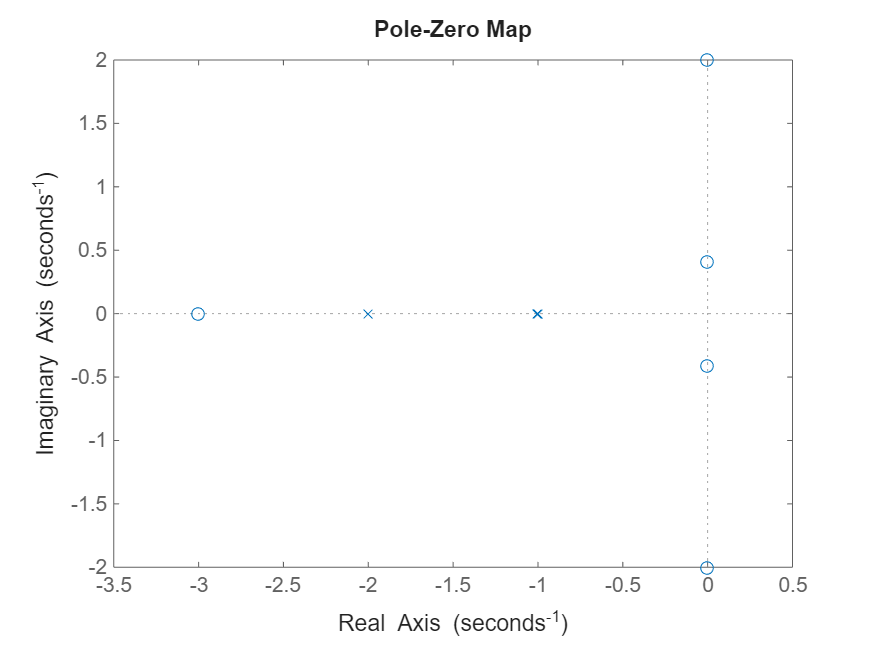

pzmap(numgh,dengh)

%L0: Exercise 2

nps=[1 2 1];
qps=[1 1];
%i. p(s)q(s) 
pq=tf(conv(nps,qps),1)


pq =
 
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties



%ii. poles and zeros of G(s) = q(s)/p(s)
[z,p,k]=tf2zp(qps,nps)

z = -1

p =     -1
    -1


k = 1


%iii. p(-1) 
gpq=tf(qps,nps)


gpq =
 
      s + 1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


polyval(p,-1)

ans = 0

%L0: Exercise 3

ne3=[1 6 8];
de3=[1 8 12 16 20];
gse3=tf(ne3,de3)


gse3 =
 
           s^2 + 6 s + 8
  --------------------------------
  s^4 + 8 s^3 + 12 s^2 + 16 s + 20
 
Continuous-time transfer function.
Model Properties



zpk(gse3)


ans =
 
           (s+4) (s+2)
  -----------------------------
  (s+6.449) (s+1.551) (s^2 + 2)
 
Continuous-time zero/pole/gain model.
Model Properties


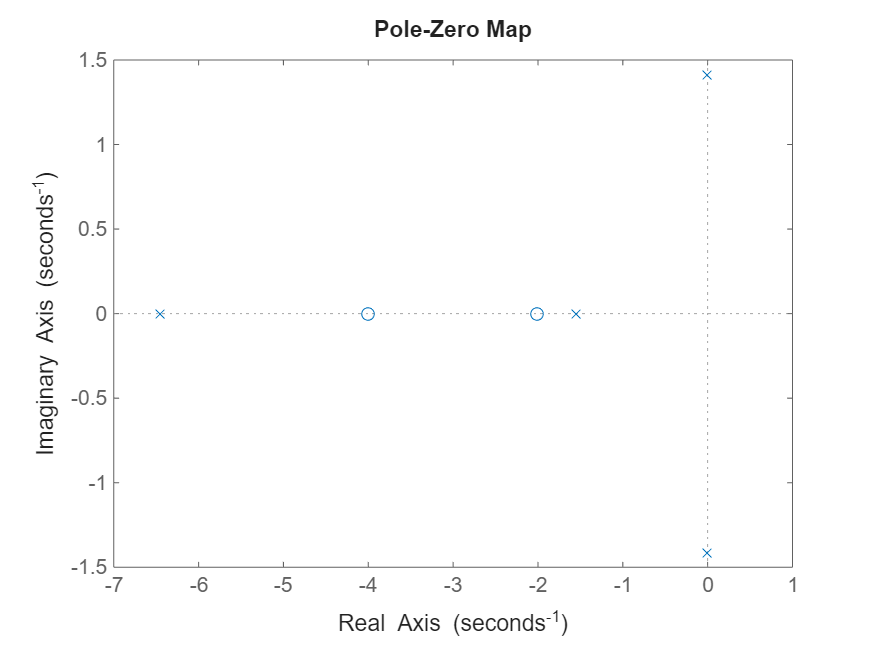


pzmap(gse3)